# Solution to *Wright Flyer Wind Tunnel Test II* exercise

## 1. Load data

load wrightWindTunnel

## 2. Calculate coefficient of lift


$$C_L = \frac{F_L}{A \cdot P_d}$$


A = 510;
CL = lift./(A*Pd);

## 3. Plot coefficient of lift

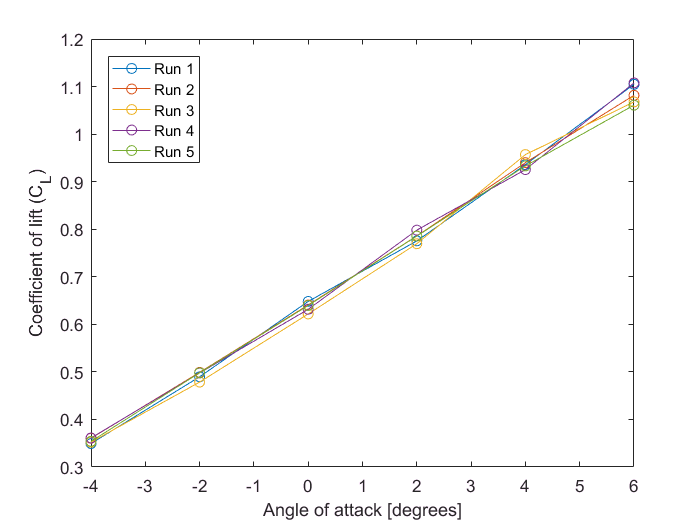

plot(alpha,CL,'o-')
xlabel('Angle of attack [degrees]')
ylabel('Coefficient of lift (C_L)')
legend('Run 1','Run 2','Run 3','Run 4','Run 5','Location','NorthWest')

## 4. Calculate mean coefficient of lift

avgCL = mean(CL,2);

## 5. Create scatter plot and use basic fitting tool

plot(alpha,avgCL,'o')
xlabel('Angle of attack [degrees]')
ylabel('Coefficient of lift (C_L)')

Programmatic version of Basic Fitting Tool:

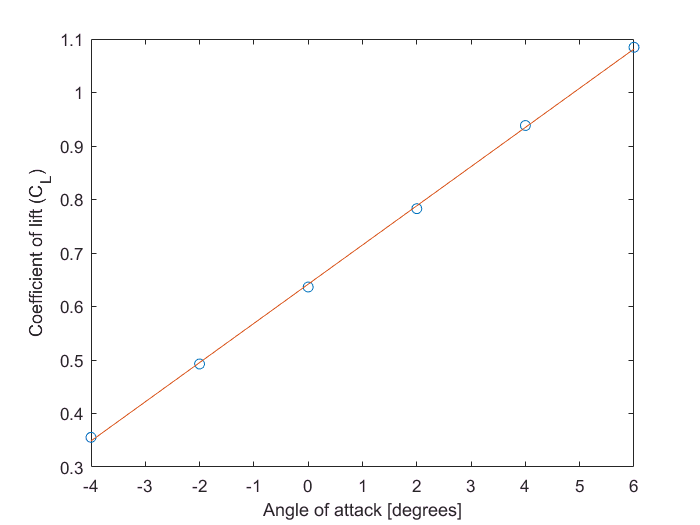

c = polyfit(alpha,avgCL',1);
fitAvgCL = polyval(c,alpha);
hold on
plot(alpha,fitAvgCL)
hold off